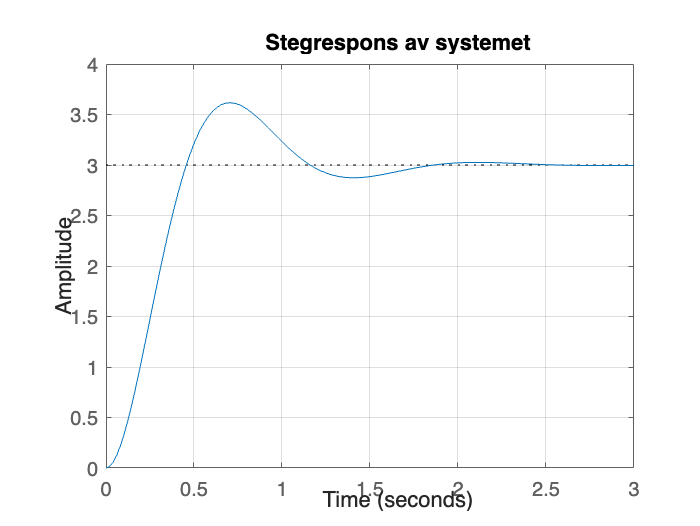

% Parametere for systemet
K = 3; %Amplitude
omega_n = 5;
zeta = 0.45;

% Sett opp transferfunksjonen
numerator = K * omega_n^2;
denominator = [1, 2*zeta*omega_n, omega_n^2];
G = tf(numerator, denominator);

% Plot stegresponsen
figure;
step(G);
title('Stegrespons av systemet');
grid on;


% Hent stegrespons-info
info = stepinfo(G);

% Vis resultater
fprintf('Stigetid (Rise Time): %.2f sek\n', info.RiseTime);

Stigetid (Rise Time): 0.31 sek


fprintf('Innsvingningstid (Settling Time): %.2f sek\n', info.SettlingTime);

Innsvingningstid (Settling Time): 1.67 sek


fprintf('Prosent oversving (Overshoot): %.1f%%\n', info.Overshoot);

Prosent oversving (Overshoot): 20.5%


fprintf('Toppverditid (Peak Time): %.2f sek\n', info.PeakTime);

Toppverditid (Peak Time): 0.70 sek
